clear all
clf
month = 60*60*24*30;
start_temp = -3;
R_0 = 8.6903 * (10^-4);
R_rest = 0.0055 - R_0;

[t, T] = ode45(@solarODE, [0 month], start_temp);

t = t/86400;

T_air = (T - start_temp) * (R_rest/(R_rest + R_0));
temp_high = 25;
temp_low = 17;

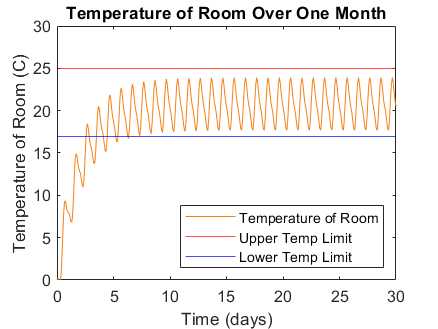

% Plot 1 month
figure()
plot (t, T_air,color="#F58216")
hold on

yline(temp_high,color="r");
yline(temp_low,color='b');
xlabel("Time (days)");
ylabel("Temperature of Room (C)")
title("Temperature of Room Over One Month")
legend("Temperature of Room", "Upper Temp Limit", "Lower Temp Limit", "Location","Southeast");
xlim([0,30])
ylim([0,30])
hold off

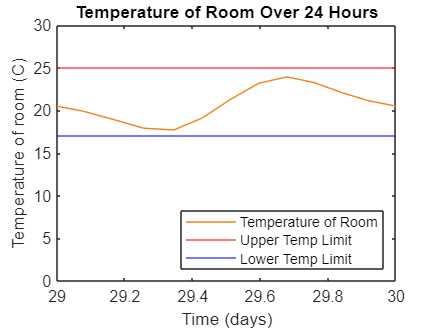

% Plot 24 hr span

figure()
plot (t, T_air,color="#F58216")
hold on

temp_high = 25;
temp_low = 17;
yline(temp_high,color="r");
yline(temp_low,color='b');

xlabel("Time (days)");
ylabel("Temperature of room (C)")
title("Temperature of Room Over 24 Hours")
legend("Temperature of Room", "Upper Temp Limit", "Lower Temp Limit", "Location","Southeast");
xlim([29,30])
ylim([0,30])
hold off